# Endmember Finding Algorithms on TI and TE dataset with MATLAB

## 1. Download the Dataset from Github and Loading the Dataset

Downloads the dataset by cloning the tite GitHub repository to the local environment. The dataset is stored in a folder named tite. Then, we can load the variables from the tite_reflectance.mat file into the MATLAB environment.

% Download Dataset
if ~exist("./tite/tite_reflectance.mat")
    gitclone("https://github.com/Brunoxue/tite.git");
end

% Load Dataset
load("tite/tite_reflectance.mat");
hsi=double(TI2);

## 2. Visualizing a Specific Band

Next, we will display a selected band (100th band in this case) of the hyperspectral image.

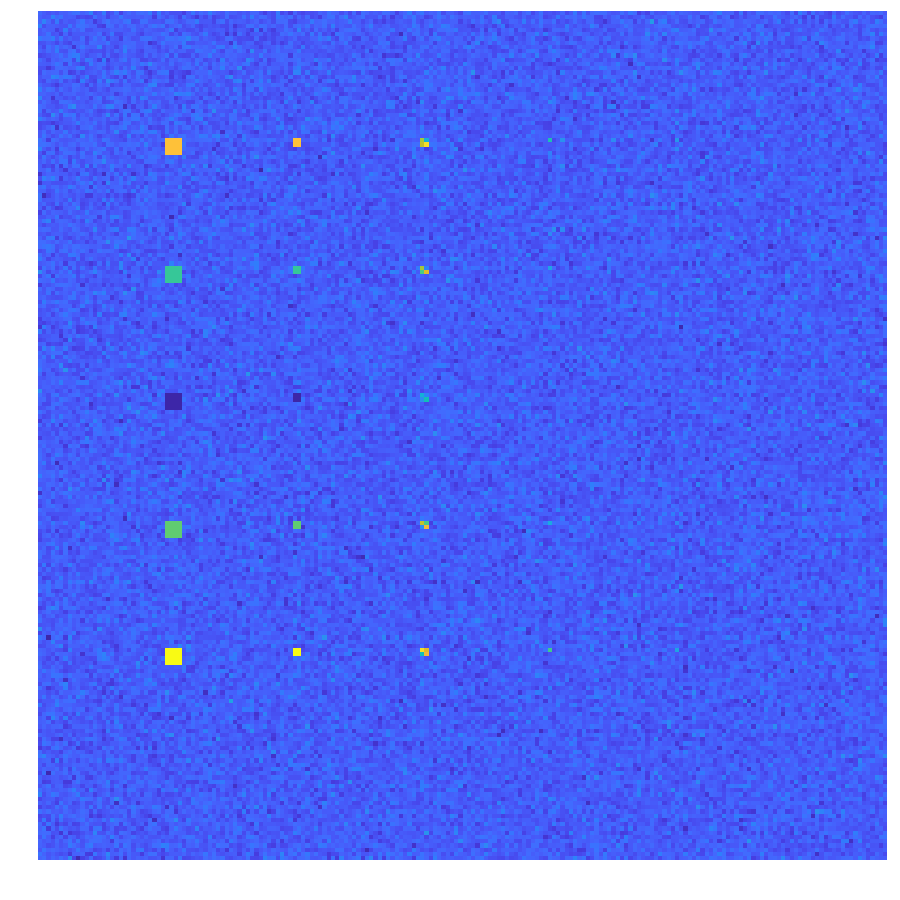

figure("Units","pixels","Position",[1,1,500,500]);
tiledlayout(1,1,"Padding","tight");

nexttile,
imagesc(hsi(:,:,100)),axis off,axis image;

## 3. Find Endmembers with Automatic Target Generation Process (ATGP)

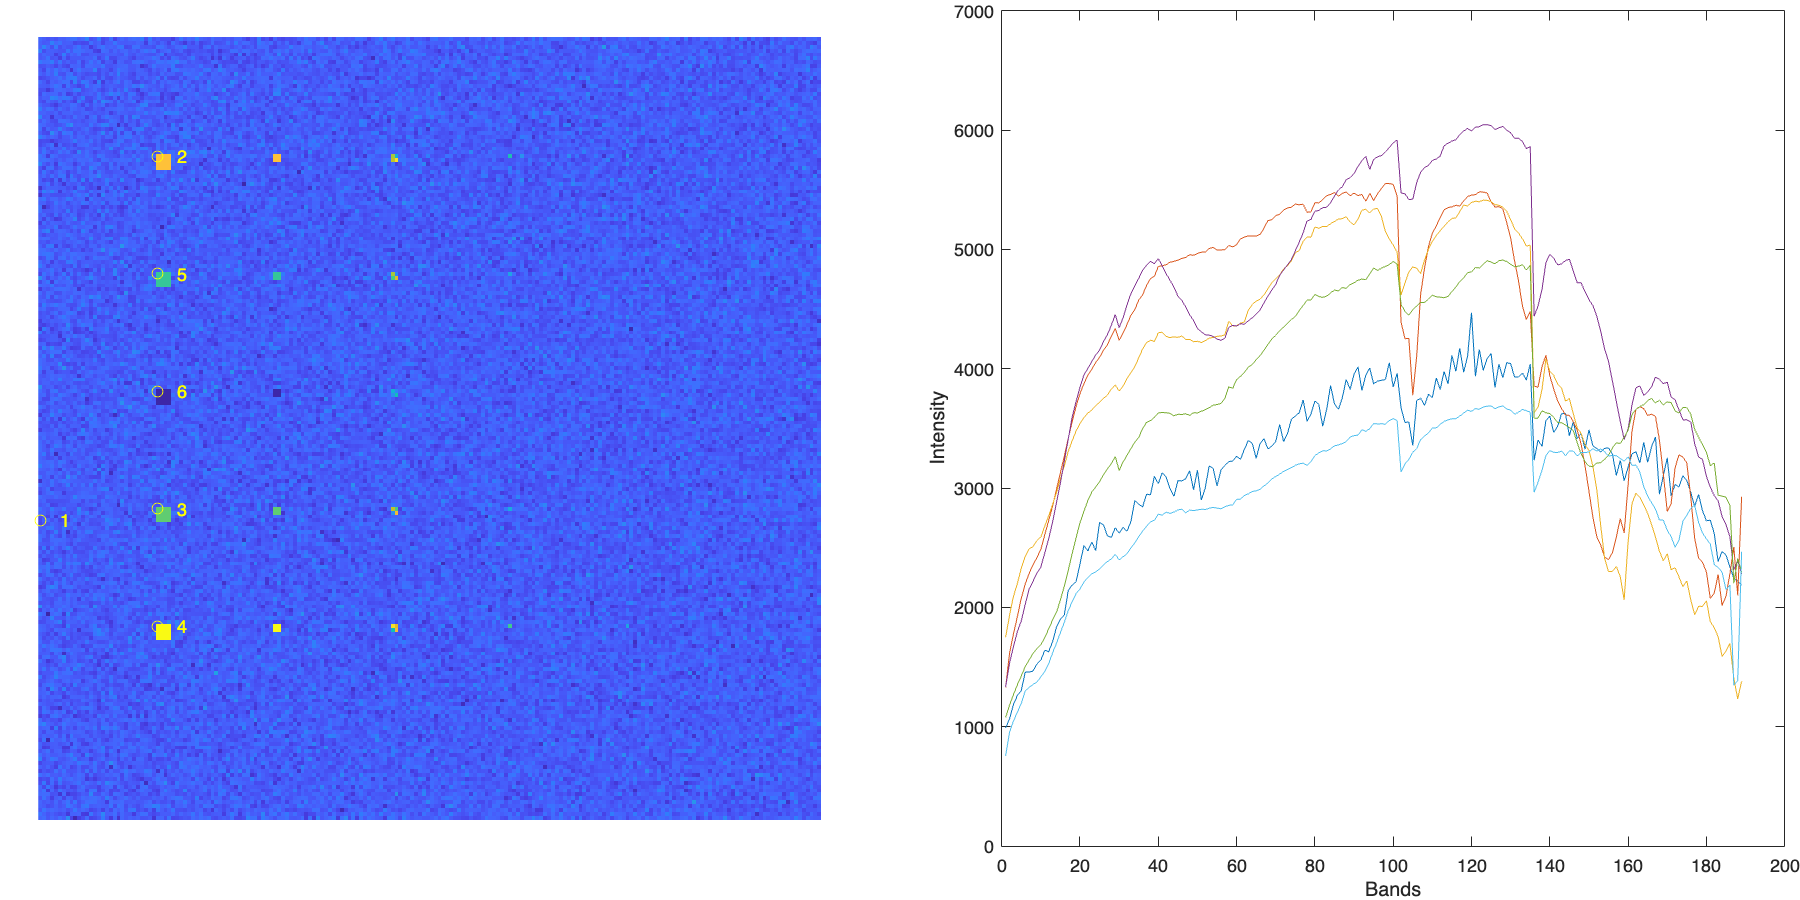

% ATGP
numTgt=6;
[posTgt,spTgt] = ATGP(hsi,numTgt);

figure("Units","pixels","Position",[1,1,1000,500]);
tiledlayout(1,2,"Padding","tight");

nexttile,
imagesc(hsi(:,:,100)),axis off,axis image;
for idx = 1:numTgt
    hold on,plot(posTgt(idx,2),posTgt(idx,1),'yo');
    hold on,text(posTgt(idx,2)+5,posTgt(idx,1),num2str(idx),"Color","yellow");
end

nexttile;
plot(spTgt);
xlabel("Bands");
ylabel("Intensity");

## 4. Find Endmembers with N-FINDR

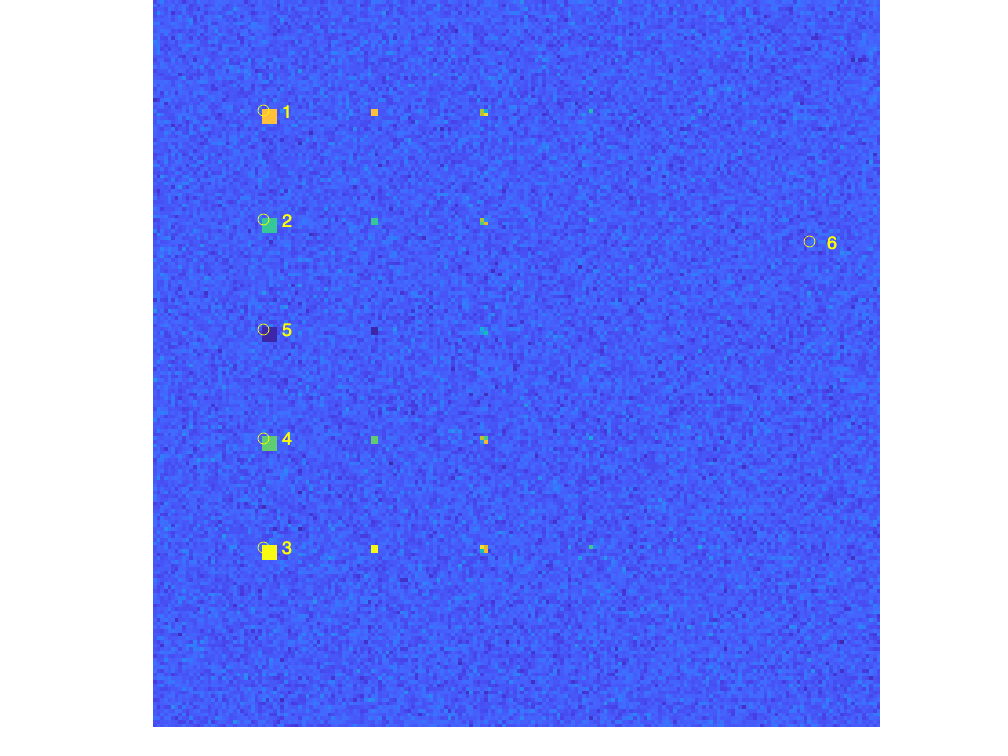

% NFINDR
posTgt=NFINDR(hsi,numTgt);

figure("Units","pixels","Position",[1,1,1000,500]);
tiledlayout(1,2,"Padding","tight");

nexttile,
imagesc(hsi(:,:,100)),axis off,axis image;
for idx = 1:numTgt
    hold on,plot(posTgt(idx,1),posTgt(idx,2),'yo');
    hold on,text(posTgt(idx,1)+5,posTgt(idx,2),num2str(idx),"Color","yellow");
end

## 5. Find Endmembers with Simplex Growing Algorithm** (SGA)**

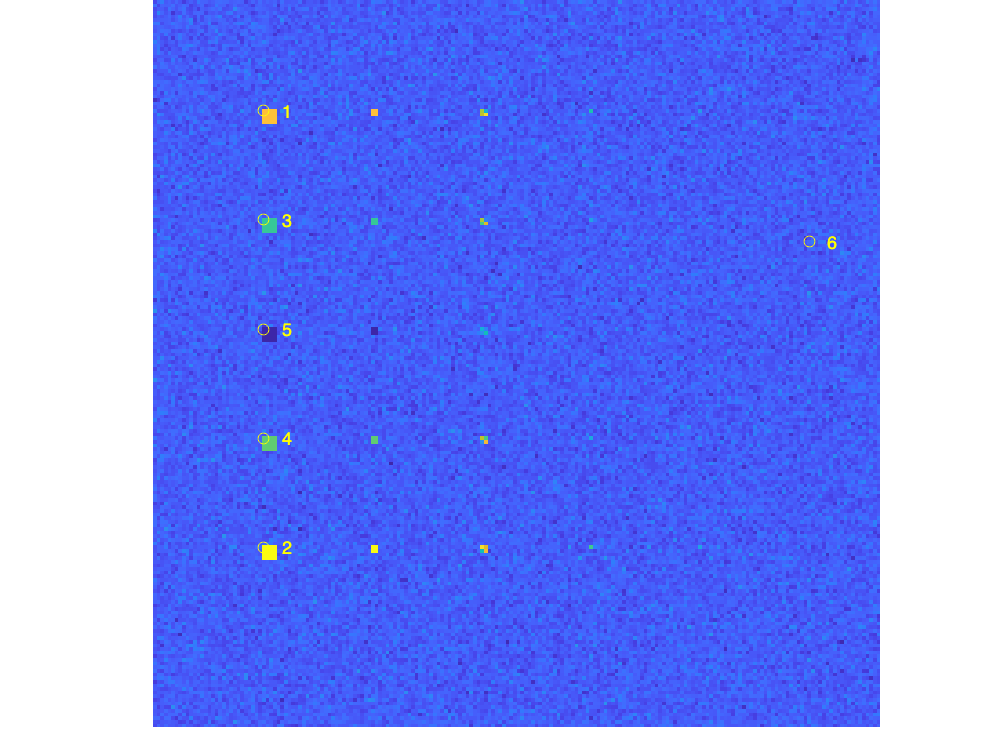

% SGA
posTgt=SGA(hsi,numTgt);

figure;
tiledlayout(1,1,"Padding","tight");

nexttile,
imagesc(hsi(:,:,100)),axis off,axis image;
for idx = 1:numTgt
    hold on,plot(posTgt(idx,1),posTgt(idx,2),'yo');
    hold on,text(posTgt(idx,1)+5,posTgt(idx,2),num2str(idx),"Color","yellow");
end

## Functions for Above Tasks

% Subfunctions
% ATGP
function [posTgt,spTgt]=ATGP(HSI,p)
    [x,y,L] = size(HSI);
    N=x*y;

    r=reshape(HSI,N,L);

    [~,idxTgt] = max(sum(r.^2,2));
    spTgt=r(idxTgt,:)';
    
    for idx=2:p
        U=spTgt;
        P_U_Per=eye(L)-U*pinv(U'*U)*U';
        scoreATGP = sum((r*P_U_Per).^2,2);
        [~,idxNewTgt] = max(scoreATGP);
        idxTgt(end+1)=idxNewTgt(1);
        spTgt(:,end+1)=r(idxNewTgt(1),:)';
    end

    [posTgt(:,1),posTgt(:,2)] = ind2sub([x,y],idxTgt);

end

% NFinder
function endmemberindex=NFINDR(imagecube,p)
    % Set initial condition
    endmemberindex=[];
    newvolume = 0;
    prevolume = -1;
    [row, column, band]=size(imagecube);
    switch_results=1;
    
    % Determine to use SVD to calculate the volume or not
    if(band > p)
          use_svd=1;
    else
          use_svd=0;
    end
    
    % Randomly select p initial endmembers
    rand('state',sum(100*clock));
    for i=1:p
          while(1)
                temp1=round(row*rand);
                temp2=round(column*rand);
                if(temp1>0 & temp2>0)
                      break;
                end
          end
          endmemberindex=[endmemberindex;[temp1 temp2]];
    end
    endmemberindex=endmemberindex';
    
    endmember=[];
    for i=1:p
          if(use_svd)
                endmember=[endmember squeeze(imagecube(endmemberindex(1,i),endmemberindex(2,i),:))];
          else
                endmember=[endmember squeeze(imagecube(endmemberindex(1,i),endmemberindex(2,i),1:p-1))];
          end
    end
    
    % calculate the endmember's volume
    if(use_svd)
          s=svd(endmember);
          endmembervolume=1;
          for i=1:p
                endmembervolume=endmembervolume*s(i);
          end
    else
          jointmatrix=[ones(1,p) ; endmember];
          endmembervolume=abs(det(jointmatrix))/factorial(p-1);
    end
    
    % The main algorithm
    while newvolume > prevolume % if the new generated endmember volume is larger than the old one, continue the algorithm
    
          % Use each sample vector to replace the original one, and caculate new volume
          for i=1:row
                for j=1:column
                      for k=1:p
                            caculate=endmember;
                            if(use_svd)
                                  caculate(:,k)=squeeze(imagecube(i, j, :));
                                  s=svd(caculate);
                                  volume=1;
                                  for z=1:p
                                        volume=volume*s(z);
                                  end
                            else
                                  caculate(:,k)=squeeze(imagecube(i, j, 1:p-1));
                                  jointmatrix=[ones(1,p);caculate];
                                  volume=abs(det(jointmatrix))/factorial(p-1); % The formula of Simplex volume
                            end
                            if volume > endmembervolume
                                  endmemberindex(:,k)=[i;j];
                                  endmember=caculate;
                                  endmembervolume=volume;
                            end
                      end
                end
          end
          prevolume=newvolume;
          newvolume=endmembervolume;
    end
    % Switch results for the standard
    if(switch_results)
          endmemberindex(3,:)=endmemberindex(1,:);
          endmemberindex(1,:)=[];
          endmemberindex=endmemberindex';
    end
end

% SGA
function endmemberindex=SGA(imagecube,p)
    % Set initial condition
    n=1;
    initial=0;
    [row, column, band]=size(imagecube);
    
    % Determine to use SVD to calculate the volume or not
    if(band > p)
        use_svd=1;
    else
        use_svd=0;
    end
    
    % Randomly Select a point as the initial point
    endmemberindex=[ceil(row*rand);ceil(column*rand)];
    
    % The main algorithm
    while n<p % if get enough endmember group, it stops
    
	    % Generate endmember vector from reduced cub
	    endmember=[];
	    for i=1:n
            if(use_svd)
                endmember=[endmember squeeze(imagecube(endmemberindex(1,i),endmemberindex(2,i),:))];
            else
                endmember=[endmember squeeze(imagecube(endmemberindex(1,i),endmemberindex(2,i),1:n))];
            end
	    end
    
	    % Use each sample vector to caculate new volume
	    newendmemberindex=[];
	    maxvolume=0;
	    for i=1:row
		    for j=1:column
                if(use_svd)
                    jointpoint=[endmember squeeze(imagecube(i,j,:))];
                    s=svd(jointpoint);
                    volume=1;
                    for z=1:n+1
                        volume=volume*s(z);
                    end
                else
                    jointpoint=[endmember squeeze(imagecube(i,j,1:n))];
                    jointmatrix=[ones(1,n+1);jointpoint];
                    volume=abs(det(jointmatrix))/factorial(n); % The formula of a simplex volume
                end
			    if volume > maxvolume
				    maxvolume=volume;
				    newendmemberindex=[i;j];
			    end
		    end
	    end
	    endmemberindex=[endmemberindex newendmemberindex]; % Add this pixel into the endmember group
	    n=n+1;
	    if initial==0, % Use new pixel as the initial pixel
		    n=1;
		    endmemberindex(:,1)=[];
		    initial=initial+1;
	    end
    end
        
    % Switch the results back to X and Y
    endmemberindex(3,:)=endmemberindex(1,:);
    endmemberindex(1,:)=[];
    endmemberindex=endmemberindex';
end